clc
clear all
close all

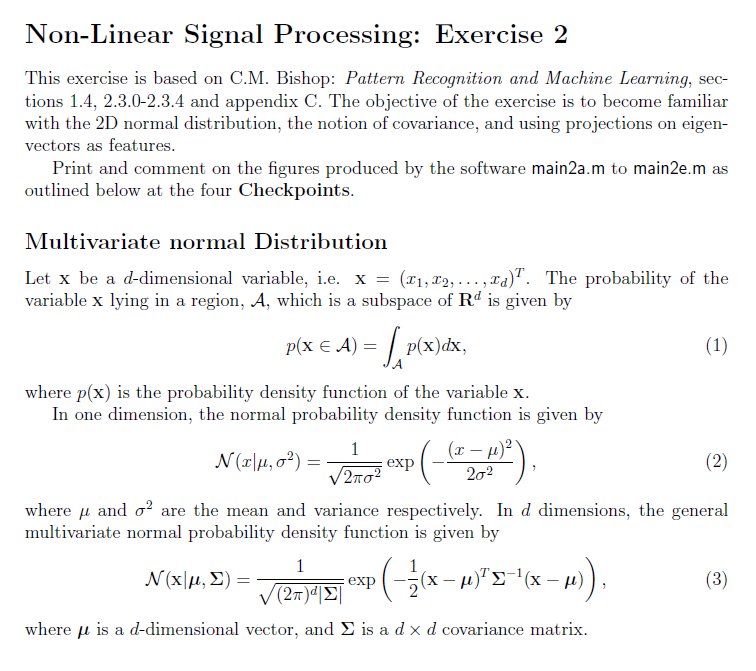

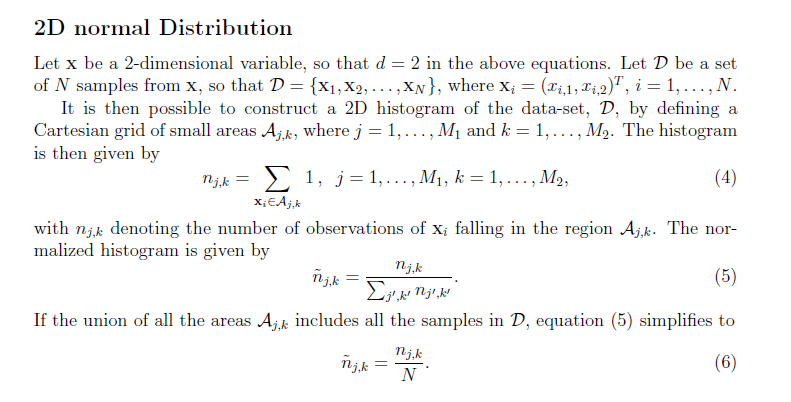

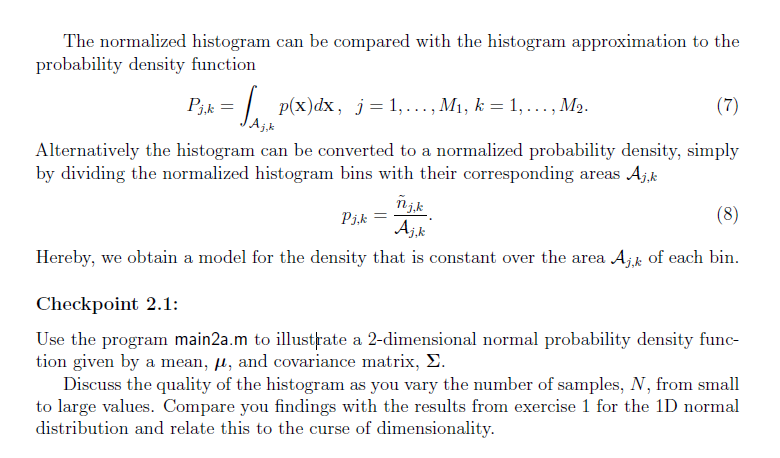

In order to probe the quality of the histogram we have shown the results with three different number of samples: $N=100$ $N=1000$ and $N=1000$0 

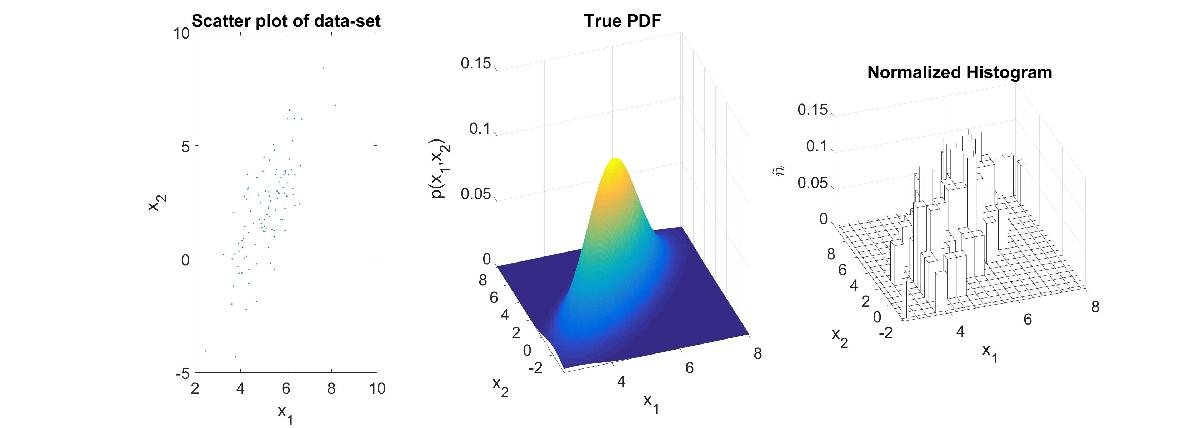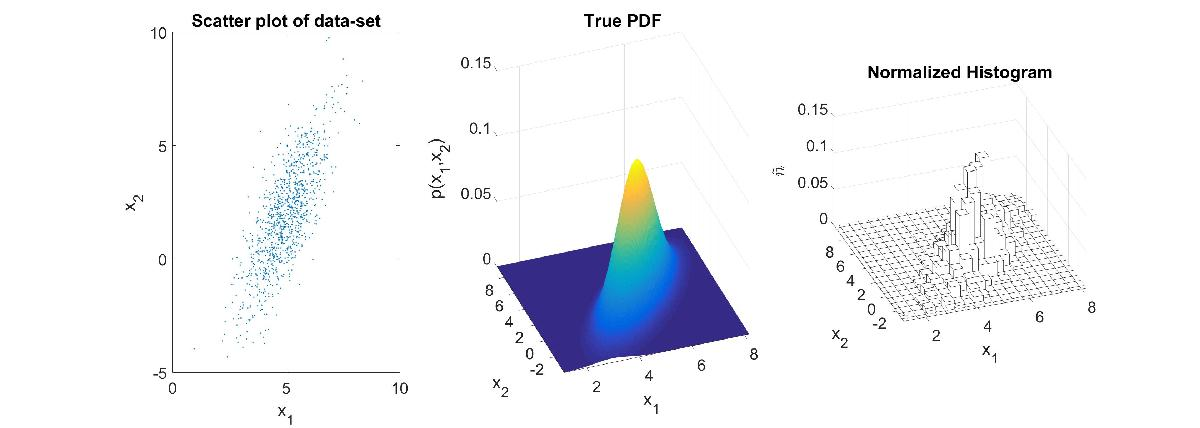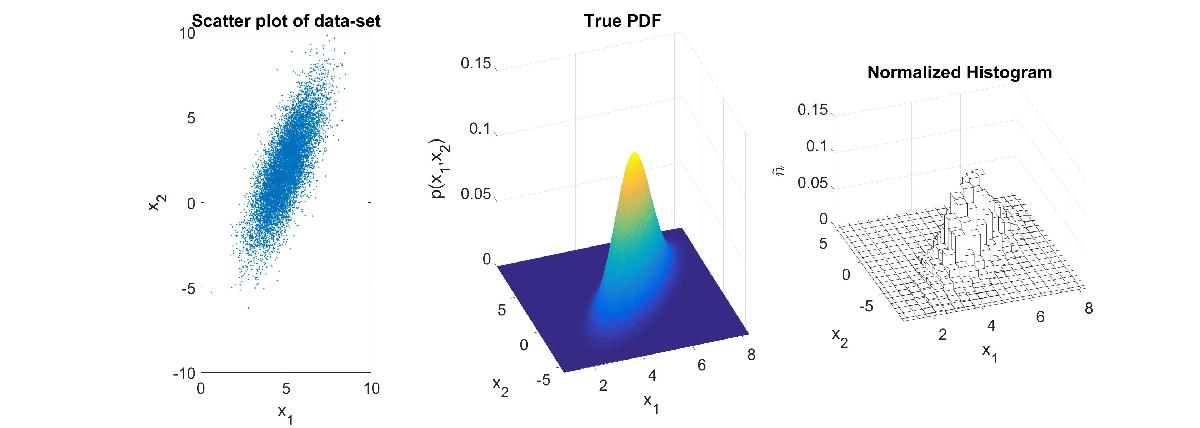

In the case of N=100 the results does not look like a normal distribution at all, but we see how does it look more and more like one with the increments of samples. However, the number of samples needed to get an accuracy similar to the error that we get in the one dimensional case is way bigger, mainly due to the course of dimensionality. 

This term is a phenomena that arises when working with high dimensions of data. It mainly states that the density of the distribution decreases exponentionally when introducing new dimensions of data, and with that, in our case the quality of the histogram. In order to mantain the same sampling density we should keep  $N^{\frac{1}{D}}$ proportional, being N the number of samples and D the number of dimensions. In our case, if we want to maintain the same density as in the one dimensional case with N=20 samples we should obtain:


$$20^{\frac{1}{1}}=N_{2D}^{\frac{1}{2}}$$



$$N_{2D}=400 $$


We can test this course of dimensionality by comparing the error between the estimated histogram and the true histogram for the one dimensional and the two dimensional case, respectively.

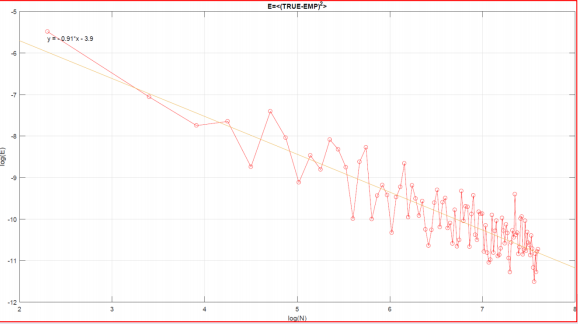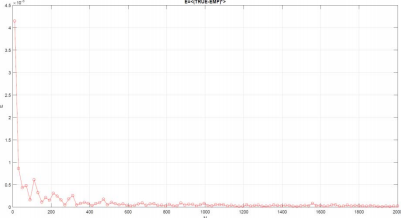

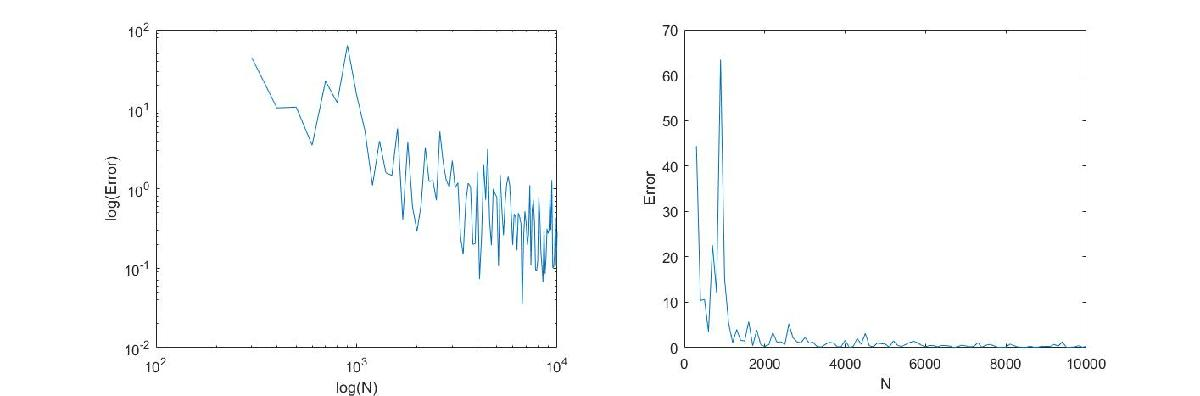

As we can see, the shape is similar, but when we take a look at the scale, the differences are obvious. (ASK ABOUT THIS)

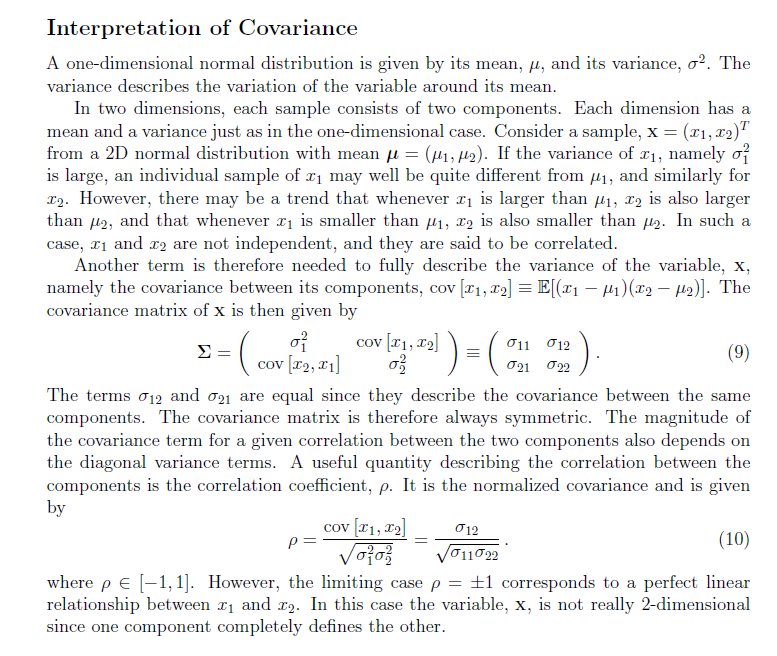

0 cov, linear, hor, vertical 4 diferent options 

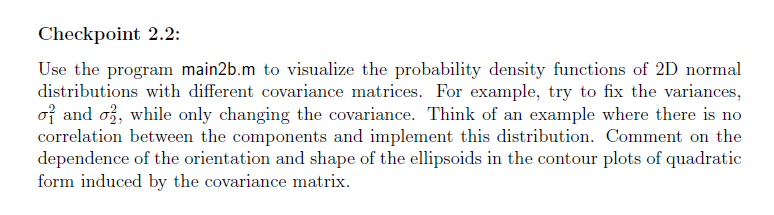

After performing this experiment we have came up with 3 different singular cases: 

- Uncorrelated distributions:  $\sigma_{12}=0$

In this case we have two completely independent components, so that the values of one component does not affect the other one.                                     One example of this could be a dataset with information about shoe size and yearly income, two completely unrelated components. In this case, as we can see the shape is a vertical elipsoid because $\sigma_{11}$ is bigger than $\sigma_{12}$. In the other case, we  would see a distribution that is more spread in the horizontal axis. 

   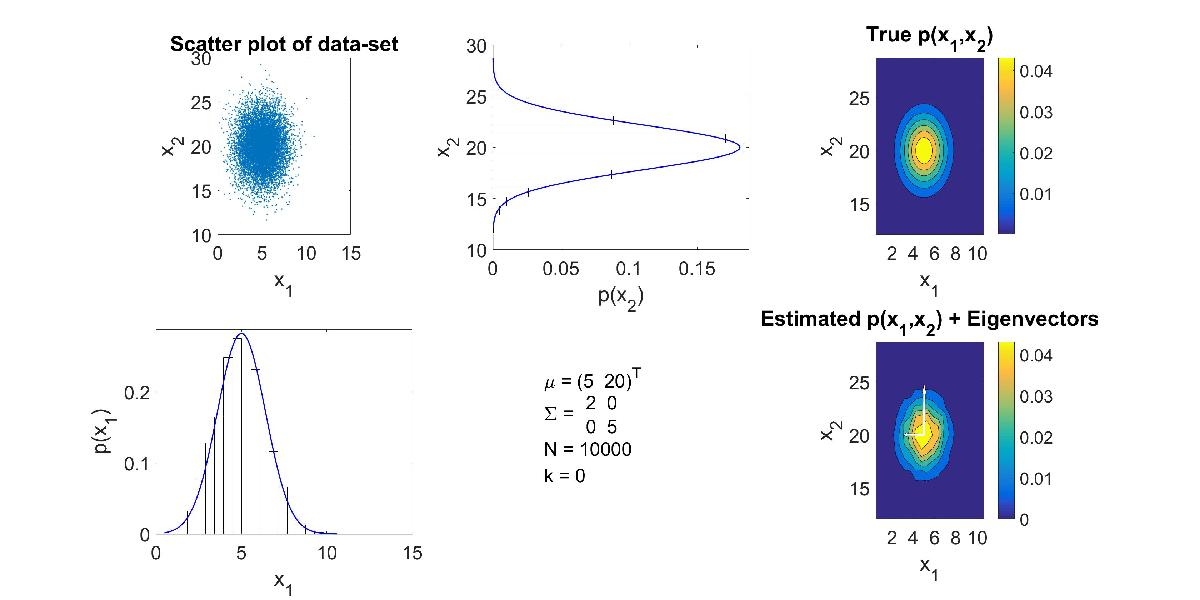

- Covariance matrix proportional to the identity matrix  $\sigma_{12}=0$  | $\sigma_{11}=\sigma_{22}$

Two distributions with the same variance and completely uncorrelated. The contours will adopt a perfect concentric circles shape, as they will be representing the same gaussian distribution (with different means). 

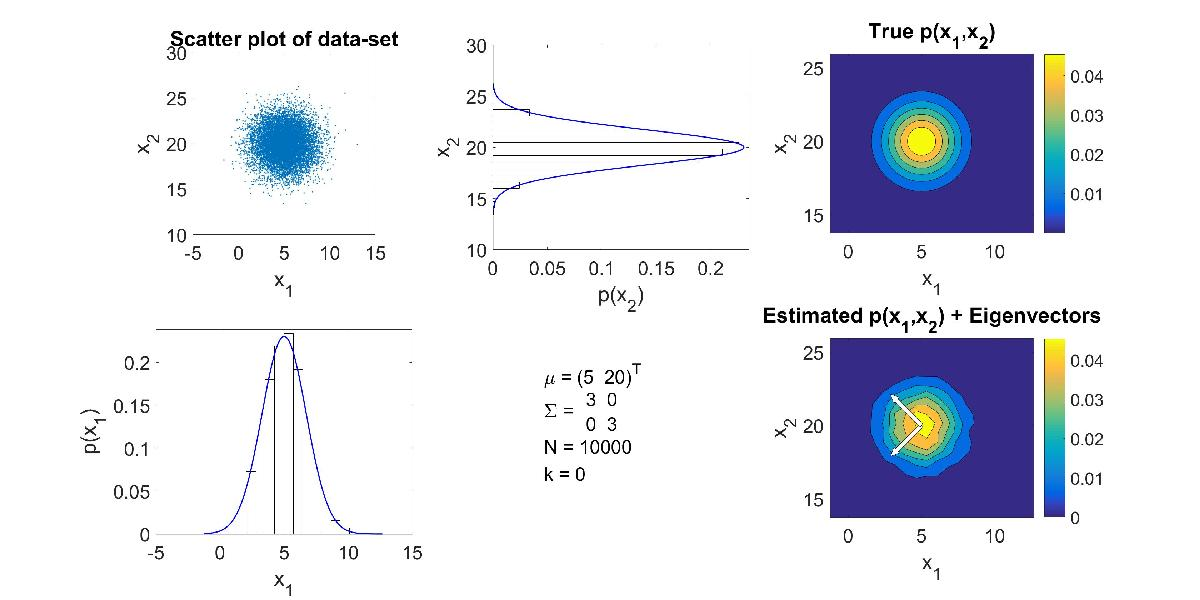

- Linear distribution: $\rho = \frac{�\sigma_{12}}{\sqrt{\sigma_{11}\sigma_{22}}}=|1|$

When the correlation coefficient approaches 1 or -1 it is easy to spot how the distribution adopts the shape of a typical linear distribution. In the limit case, when the absolute value of $\rho $ is equal to one the distribution is not two dimensional anymore, as one distribution becomes dependent on the other.

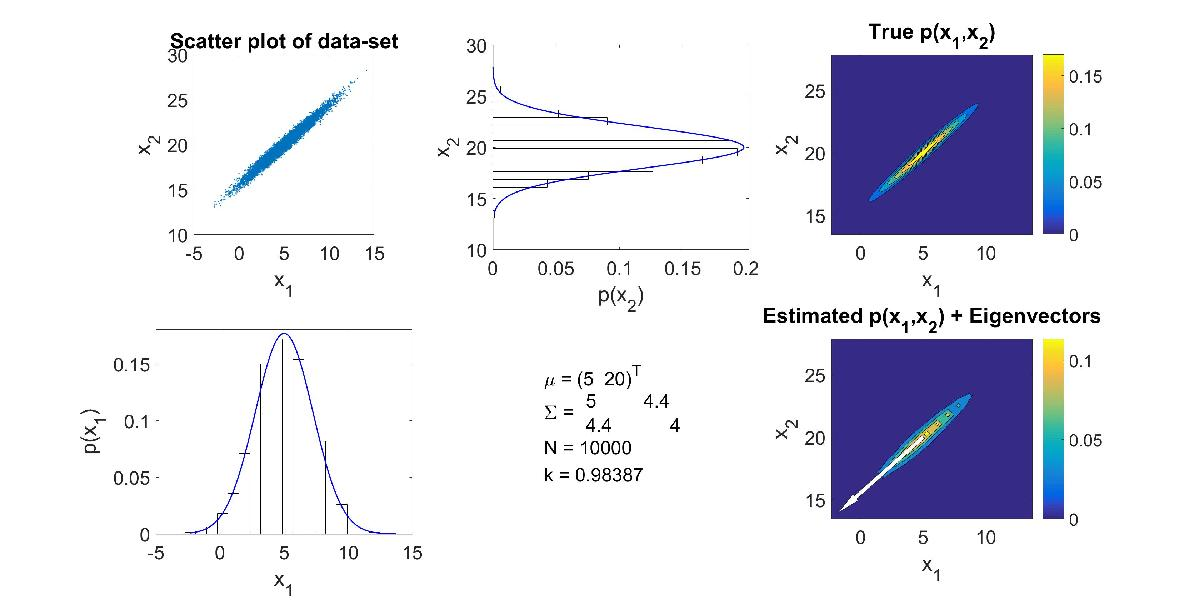

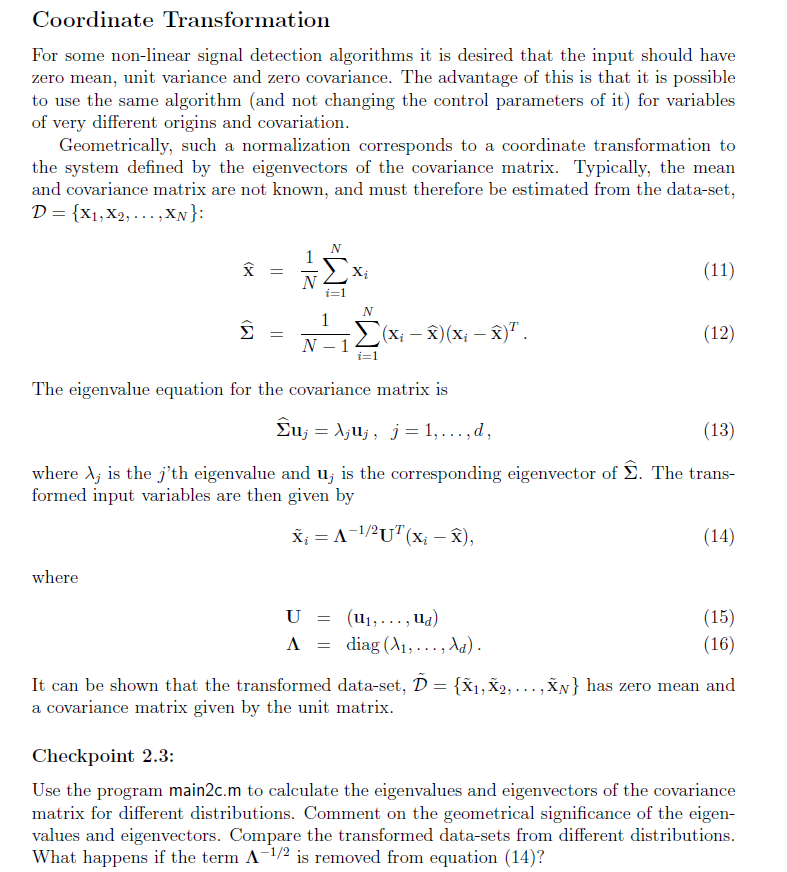

Let's first take a look at the geometrical significance of the eigenvectors and eigenvalues of a covariance matrix in a gaussian distribution. This is represented in the following image

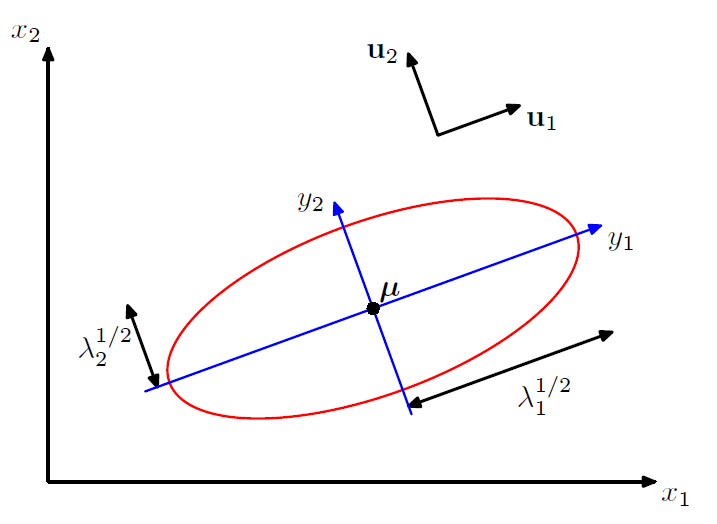

In a two dimensional casse the gaussian distributions adopt an elipsoid form, and the eigenparameters define the distinctive parameters of it. Given that the mean sets the center of the elipse, the eigenvectors define the direction of the axis of the elipse, or the direction on which the data spreads. On the other hand, the eigenvvalues are the factor that determine the size of the axis of the elipse, or how spread is the distribution in each direction given by an eigenvalue. 

We can also see this relation when executing the script: 

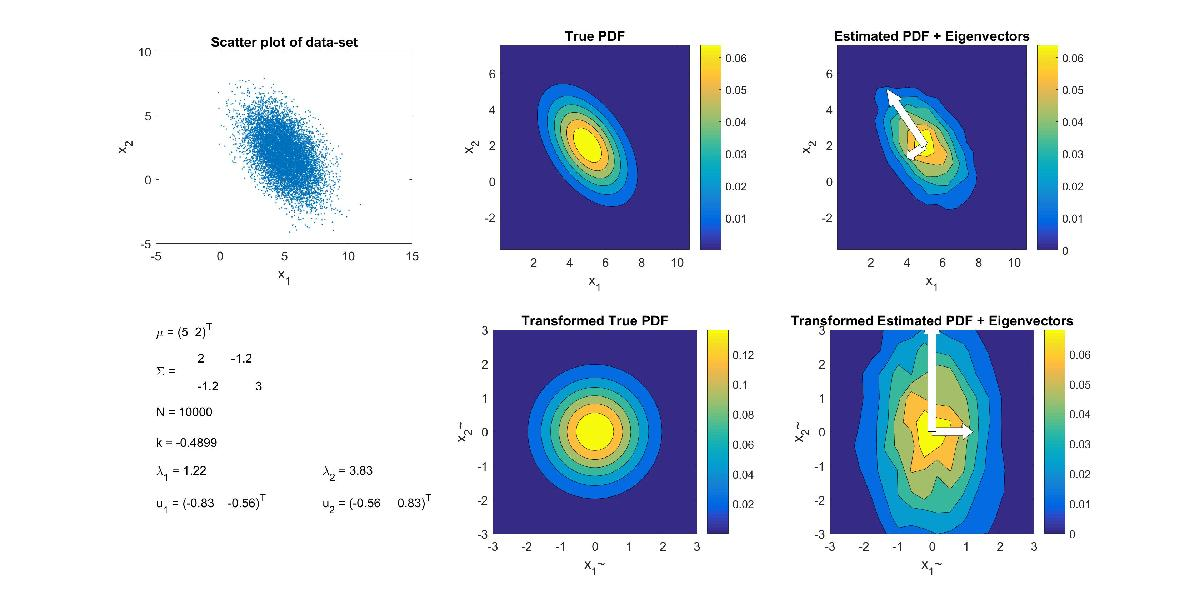

From this results we can also see how the coordinate transformation works. We can see that the distribution changed in order to have the eigenvectors as the origin of the coordinate system, rotating around the distribution. 

Some special cases worth mentioning are when we are working with independent distributions and the variance of the distributions is the same. In this case we can see that the eigenvector's directions move depending on the introduced noise when producing the data. 

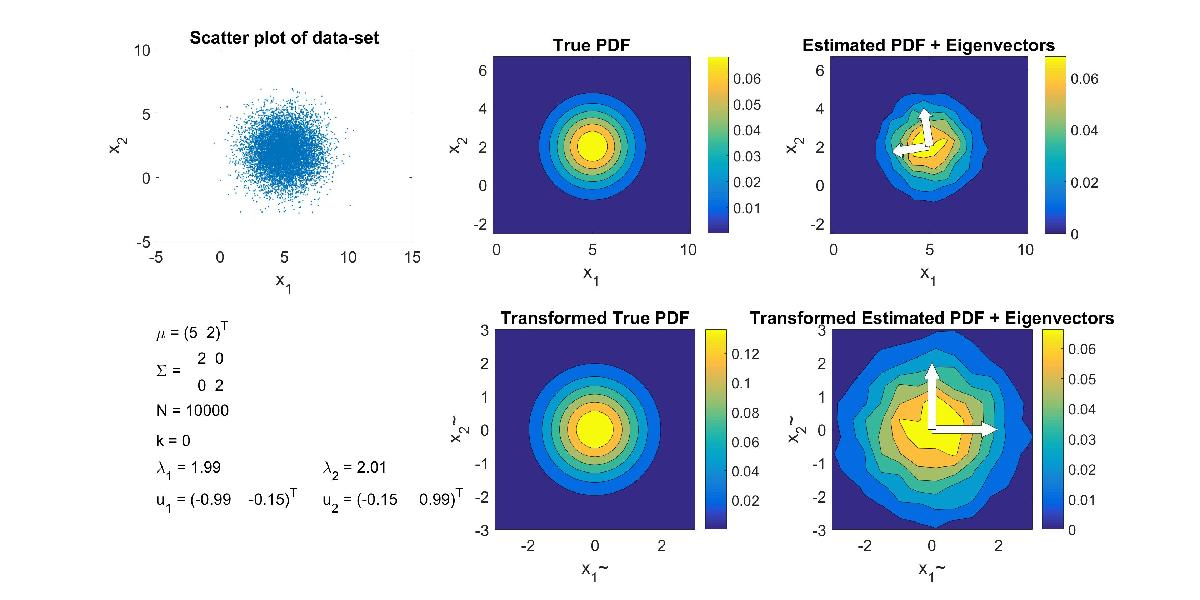

Regarding the term, it is important to note that it has not been introduced in the previous cases. We can realise because if we take a look at the transformed true PDF of the first example, the distribution are elipses and not a circle as the variance is not scaled. 

The term rotates

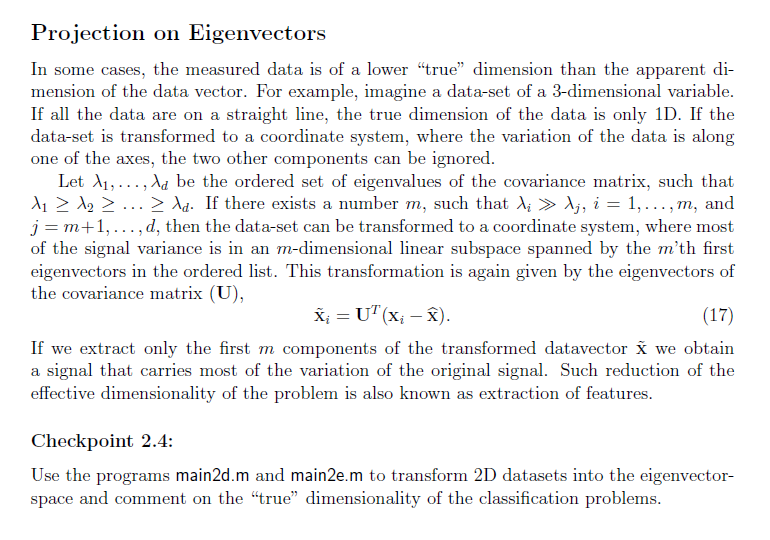

In the programs we are presented with two different datasets based on two gaussian distributions each. The first one is presented below:

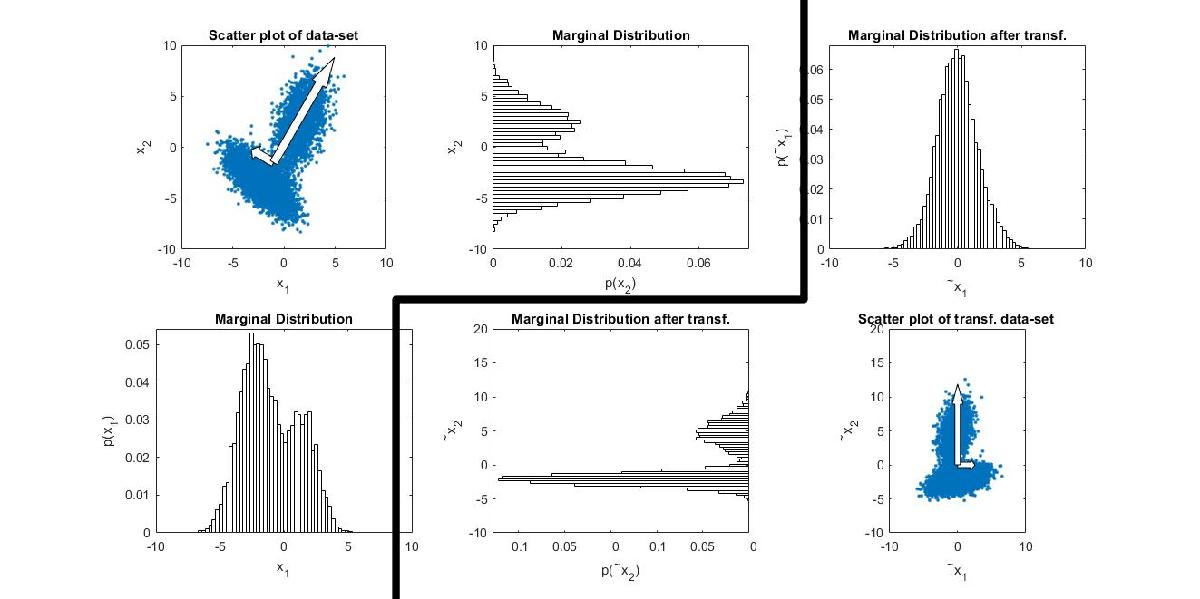

In this figure we can see the same dataset before (left) and after (right) the coordinate transformation. Before the coordinate transformation both axis seem to be holding some features about the data. However, after applying the transformation we can see that the x1 axis is just a normal distribution, which may lead us to think that this dimension is not holding any valuable feature for our model, and all the features are in the axis with the biggest eigenvalue, x2. However, where to place the threshold between the difference of eigenvectors can depend on our dataset, model and application. For example, even though we are seen a normal distribution in the x axis we can note the difference between distributions when looking at the data. 

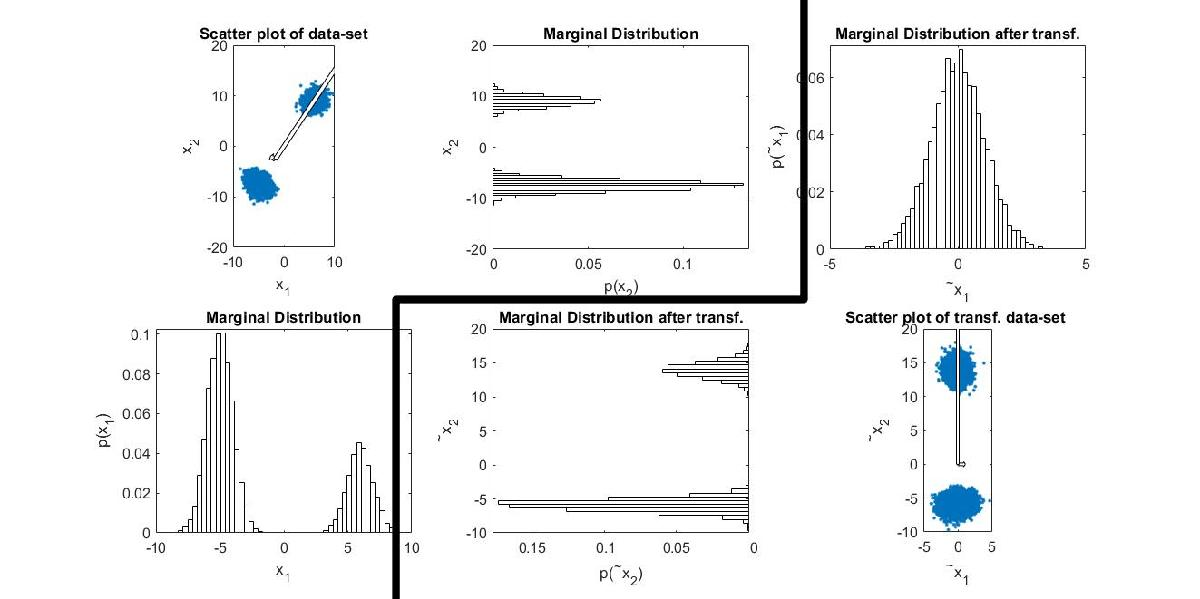

In the case of the next program the number of features to be extracted from the x1 axis is even smaller, as we can note from the relative size of the eigenvectors.

This dimensionality reduction can be useful from a machine learning perspective due to different reasons. First of all, it will reduce the size of your data in memory, with the consecuence improvement in speed. Secondly, this removal of multi-colinearity improves the performance of the ML models. This can be visualized by taking the previous example and adding noise to one of the gaussian distributions.

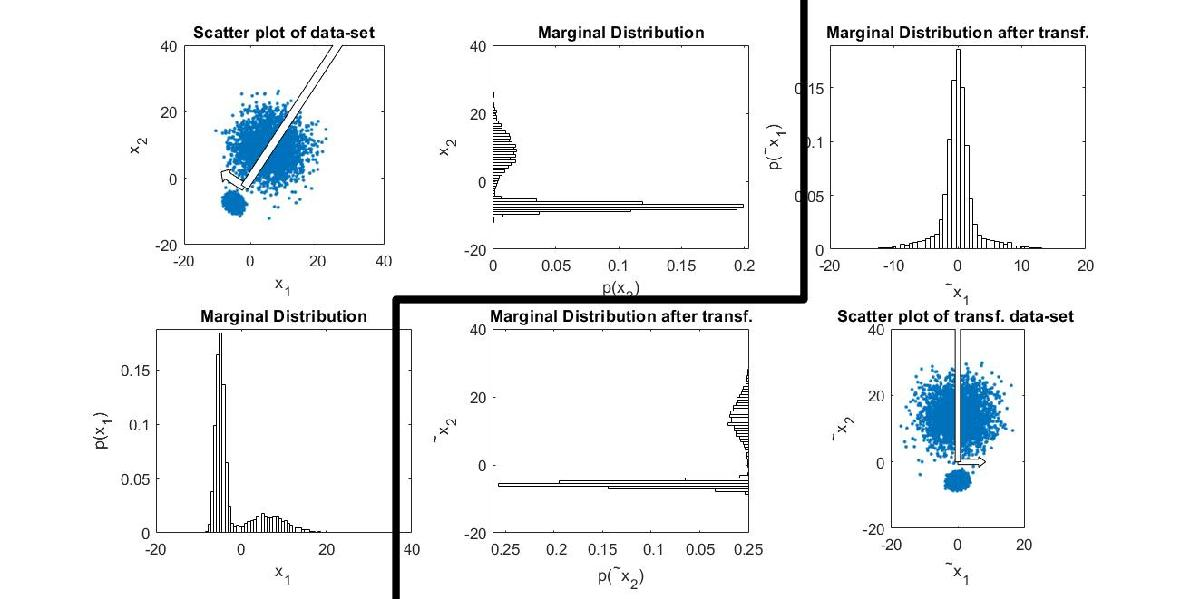

It can be noted that the x1 axis is not that similar to a gaussian distribution anymore, and it may seem like you can extract some features from that axis as well. However, if you do, you are risking to overfit your model to your training data, as you are just modelling noise in that dimension. 

Finally, when reducing the dimensions enough it becomes possible to visualize them. making it easier to work with them. 